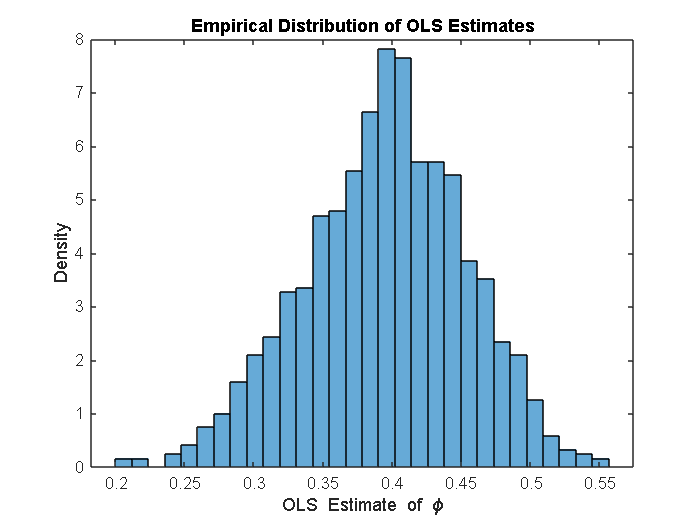

Mean of OLS estimates: 0.39483
Standard deviation of OLS estimates: 0.05831


%EXCERCISE 5
function empirical_OLS_distribution(phi, T, noise_var, num_simulations)
    % Inputs:
    % phi               - True AR(1) coefficient (e.g., 0.4)
    % T                 - Number of observations (e.g., 250)
    % noise_var         - Variance of the white noise (innovation)
    % num_simulations   - Number of simulations to run (e.g., 1000)
    
    % Preallocate a vector to store the OLS estimates
    ols_estimates = zeros(num_simulations, 1);
    
    % Run the simulations
    for sim = 1:num_simulations
        % Generate white noise
        epsilon = sqrt(noise_var) * randn(T, 1);
        
        % Initialize the AR(1) process
        y = zeros(T, 1);
        y(1) = epsilon(1);  % Initial value
        
        % Generate the AR(1) process
        for t = 2:T
            y(t) = phi * y(t-1) + epsilon(t);
        end
        
        % Estimate the AR(1) coefficient using OLS
        y_lag = y(1:end-1);  % Lagged values of y
        y_curr = y(2:end);   % Current values of y
        
        % OLS estimate: regress y_curr on y_lag
        ols_estimates(sim) = (y_lag' * y_lag) \ (y_lag' * y_curr);
    end
    
    % Plot the empirical distribution of the OLS estimates
    figure;
    histogram(ols_estimates, 30, 'Normalization', 'pdf');
    title('Empirical Distribution of OLS Estimates');
    xlabel('OLS Estimate of \phi');
    ylabel('Density');
    
    % Display the mean and standard deviation of the OLS estimates
    ols_mean = mean(ols_estimates);
    ols_std = std(ols_estimates);
    disp(['Mean of OLS estimates: ', num2str(ols_mean)]);
    disp(['Standard deviation of OLS estimates: ', num2str(ols_std)]);
end

% Example usage:
phi = 0.4;
T = 250;
noise_var = 1;  % Choose a variance for the white noise
num_simulations = 1000;  % Run 1000 simulations

empirical_OLS_distribution(phi, T, noise_var, num_simulations)